# Mesh Class

## 1D Line Mesh

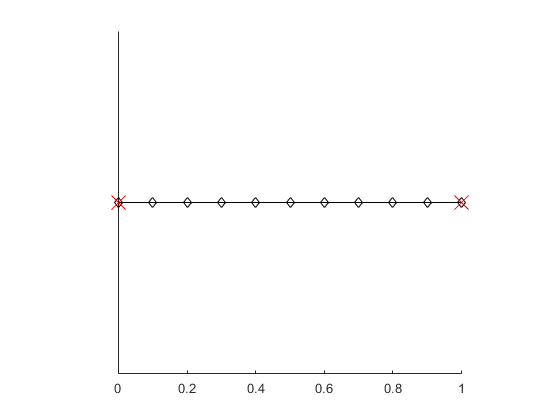

mesh = line2linemesh(); % get uniform line mesh
figure;
mesh.show();
hold on;
plot(mesh.x4fb, zeros(1, mesh.nrfb), 'rx', 'markersize', 15)

% Mesh affine information (r in T_ref) -> (x in T)

ans =    20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000
    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500


[mesh.rx;mesh.J]
mesh.xr

ans =     0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500


## 2D triangular mesh

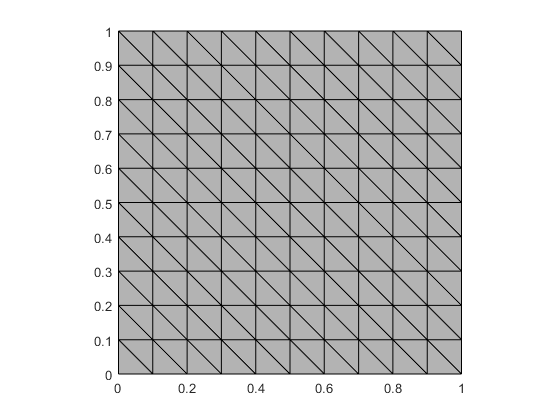

mesh = rect2trimesh(); % get uniform triangular mesh
figure;
mesh.show();

% Mesh affine information (r,s in T_ref) -> (x,y in T)
[mesh.rx; mesh.ry;
 mesh.sx; mesh.sy;
 mesh.J]

ans =    20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000   20.0000  -20.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

[mesh.xr; mesh.xs;
 mesh.yr; mesh.ys]

ans =     0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500    0.0500   -0.0500
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

## 2D random triangular mesh

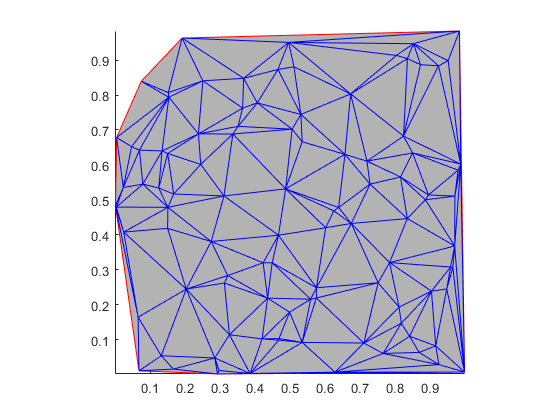

% generate random vertices
V = rand(100,2);
v4tri = delaunay(V(:,1), V(:,2)).';
% make object
mesh = Mesh(v4tri, V(:,1), V(:,2));

figure;
mesh.show();
hold on;
% show interior, boundary facets
plot(mesh.x4fb, mesh.y4fb, 'r');
plot(mesh.x4f0, mesh.y4f0, 'b-');

% Affine information can be obtained similarly.
mesh.rx

ans =     9.4290  -71.4345   -4.3680  -18.0349  -77.5865  -29.9890   10.3548  -57.1462   12.8683   -0.5261  -18.6095    2.1597   38.3858   -0.2486  -19.1978  -13.6539  -85.2016  -24.7514   22.1599  -73.6463   18.8140  -41.4103   -6.2809  -15.5218  -39.8650  -10.9525    2.3765   12.8481    6.1260  -48.2416  -43.4474  128.1955   45.1536   14.0228   -1.3111   29.5944   -0.9169   26.4572   13.2889   24.1595    9.5056  367.7677    4.9499  -13.9917   -8.7188   -2.5138   28.8650    8.6072  -11.3197   28.3706


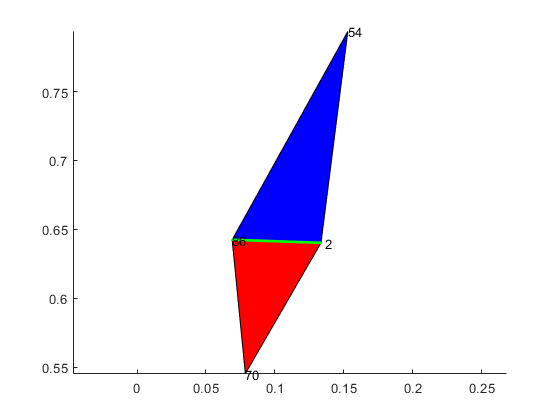


figure;
% neighboring element info
% positive element of 10th interior face
patch('XData', mesh.x4e(:, mesh.e4f0(1,10)), 'YData', mesh.y4e(:, mesh.e4f0(1,10)), 'facecolor', 'r');
% negative element of 10th interior face
patch('XData', mesh.x4e(:, mesh.e4f0(2,10)), 'YData', mesh.y4e(:, mesh.e4f0(2,10)), 'facecolor', 'b');
% 10th interior face
hold on; plot(mesh.x4f0(:,10), mesh.y4f0(:,10), 'g', 'linewidth', 2);

vertices = unique(reshape(mesh.v4e(:, mesh.e4f0(:,10)), [], 1));
text(mesh.x(vertices), mesh.y(vertices), num2str(vertices));
axis equal;

mesh.v4e(:, mesh.e4f0(:,10)) % triangle vertex information

ans =      2    86
    86     2
    70    54


[mesh.v4e(mesh.fmask(:,mesh.ef4f0(1,10)), mesh.e4f0(1,10)), ... % positive element's local facet with positive ordering
 mesh.v4e(mesh.fmask_neg(:,mesh.ef4f0(2,10)), mesh.e4f0(2,10)), ... % negative element's local facet with negative ordering
 mesh.v4f0(:,10)] % target edge

ans =      2     2     2
    86    86    86


## 3D tetrahedral mesh

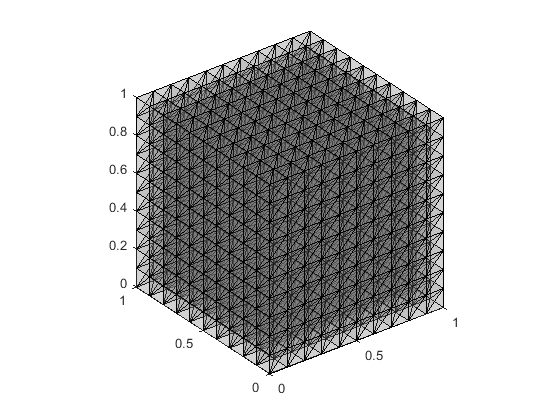

mesh = cube2tetmesh();
figure;
mesh.show();

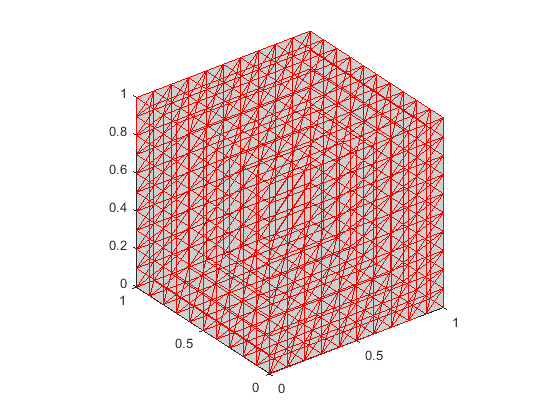

% boundary facets
figure;
patch('XData', mesh.x4fb, 'YData', mesh.y4fb, 'ZData', mesh.z4fb, 'FaceColor', 'k', 'FaceAlpha', 0.1, 'EdgeColor', 'r');
axis equal tight
view(3);

% Mesh affine information (r,s,m in T_ref) -> (x,y,z in T)
[mesh.rx; mesh.ry; mesh.rz;
 mesh.sx; mesh.sy; mesh.sz;
 mesh.mx; mesh.my; mesh.mz;
 mesh.J]

ans =    20.0000   20.0000  -20.0000  -20.0000         0         0   20.0000   20.0000  -20.0000  -20.0000         0         0   20.0000   20.0000  -20.0000  -20.0000         0         0   20.0000   20.0000  -20.0000  -20.0000         0         0   20.0000   20.0000  -20.0000  -20.0000         0         0   20.0000   20.0000  -20.0000  -20.0000         0         0   20.0000   20.0000  -20.0000  -20.0000         0         0   20.0000   20.0000  -20.0000  -20.0000         0         0   20.0000   20.0000
  -20.0000         0   20.0000         0   20.0000  -20.0000  -20.0000         0   20.0000         0   20.0000  -20.0000  -20.0000         0   20.0000         0   20.0000  -20.0000  -20.0000         0   20.0000         0   20.0000  -20.0000  -20.0000         0   20.0000         0   20.0000  -20.0000  -20.0000         0   20.0000         0   20.0000  -20.0000  -20.0000         0   20.0000         0   20.0000  -20.0000  -20.0000         0   20.0000         0   20.0000  -20.0000  -20.0000   

% facet normal and Jacobian info (works for 1D, 2D, 3D)
% also can be obtained for interior, boundary by using __4fb, __4f0
[mesh.nx4f; mesh.ny4f; mesh.nz4f; mesh.J4f]

ans =          0         0         0   -1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    1.0000         0         0   -1.0000    1.0000         0         0         0         0
         0   -1.0000         0         0   -1.0000         0   -1.0000         0   -1.0000         0   -1.0000         0   -1.0000         0   -1.0000         0   -1.0000         0   -1.0000         0   -1.0000         0   -1.0000         0   -1.0000         0   -1.0000         0   -1.0000         0   -1.0000         0   -1.0000         0   -1.0000         0   -1.0000         0   -1.0000         0   -1.0000         0         0         0         0         0         0         0         0   